3주차 MATLAB프로그래밍 과제_21010668_유현수_바이오융합공학전공

문제 1번

A = [1 4 2; 2 4 100; 7 9 7; 3 pi 42];
B = log(A);

%(a)
disp("1-(a)")

1-(a)


B(2,:)

ans =     0.6931    1.3863    4.6052



%(b)
disp("1-(b)") 

1-(b)


sum(B(2,:))

ans = 6.6846


%(c)
disp("1-(c)")
C = B(:,2).*A(:,1)

C =     1.3863
    2.7726
   15.3806
    3.4342



%(d)
disp("1-(d)")
max(C)

ans = 15.3806


%(e)
D = B(:,3);
D1 = A(1,:)'./D(1:3);
disp("1-(e)")
sum(D1)

ans = 3.3391

문제 2번***

v0 = 50;
A = 50;
g = 9.81;

%(a)
thit = (2*v0*sind(A))/g;
ymax = (v0*sind(A))^2/(2*g);
t = 0:0.01:20;
x = v0*cosd(A)*t;
y = v0*sind(A)*t - (g*t.^2)/2;

idx = find( y >= 0, 1, 'last');

thit = t(idx)

thit = 7.8000

ymax = max(y)

ymax = 74.7736

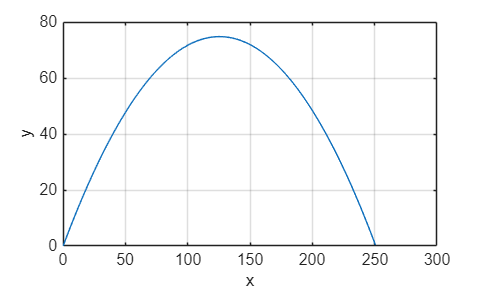




%(b)
plot(x(1:idx),y(1:idx))
xlabel('x')
ylabel('y')
grid on

문제 3번

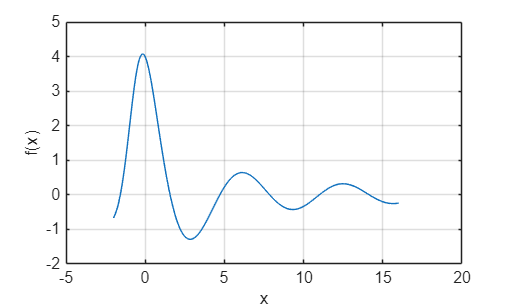

x3 = -2:0.1:16;
y3 = (4*cos(x3))./(x3+exp(-0.75*x3));
plot(x3,y3)
xlabel("x")
ylabel("f(x)")
grid on

문제 4번

%(a)
x4 = {1 300 [5 4 6]; 2 550 [3 2 4]; 3 400 [6 5 3]; 4 250 [3 5 4]; 5 500 [2 4 3]}

x4 = 5×3 cell 배열
    {[1]}    {[300]}    {[5 4 6]}
    {[2]}    {[550]}    {[3 2 4]}
    {[3]}    {[400]}    {[6 5 3]}
    {[4]}    {[250]}    {[3 5 4]}
    {[5]}    {[500]}    {[2 4 3]}


a4 = x4(:,3);
b4 = cell2mat(a4);

%(b)
disp("5월 소비량 :")

5월 소비량 :


disp(sum(b4(:,1)))

    19




%(c)
d4 =[];
for i = 1:5
    fprintf('%d재료 소비량 :',i)
    disp(sum(b4(i,:)))
    s = sum(b4(i,:));
    d4(i) = s;

    
end

1재료 소비량 :

    15



2재료 소비량 :

     9



3재료 소비량 :

    14



4재료 소비량 :

    12



5재료 소비량 :

     9




%(d)
disp("총 소비량")

총 소비량


sum(d4)

ans = 59

문제 5번

a5 = [5 0 -3 7 10];
b5 = [4 -7 9 2];

%(a)
disp("5-a")

5-a


conv(a5,b5)

ans =     20   -35    33    59   -36   -13   104    20



%(b)
c5 = [5 -7 2 8];
d5 = [6 3 -2];
disp("5-b")

5-b


deconv(c5,d5)

ans =     0.8333   -1.5833



%(c)
p5 = [36 -8 0 2];
q5 = [36 -5 4 -3];

x = 5;
disp("5-c")

5-c


polyval(p5,x)/polyval(q5,x)

ans = 0.9795

문제 7번

%(a)
bridge(1).name = "Smith St.";
bridge(1).weight = 80;
bridge(1).year = 1928;
bridge(1).end = 2025;

bridge(2).name = "Hope Ave.";
bridge(2).weight = 90;
bridge(2).year = 1950;
bridge(2).end = 2027;

bridge(3).name = "Clark St.";
bridge(3).weight = 85;
bridge(3).year = 1933;
bridge(3).end = 2024;

bridge(4).name = "North Rd.";
bridge(4).weight = 100;
bridge(4).year = 1960;
bridge(4).end = 2023;

%(b)
bridge(3).end = 2026;
disp("변경된 유지기한")

변경된 유지기한


disp(bridge(3).end)

        2026




%(c)
bridge(5).name = "Shore Rd.";
bridge(5).weight = 85;
bridge(5).year = 1997;
bridge(5).end = 2022;

bridge

bridge = 다음 필드를 포함한 1×5 struct 배열:
    name
    year
    end
    weight
